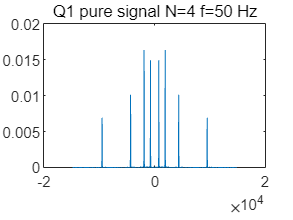

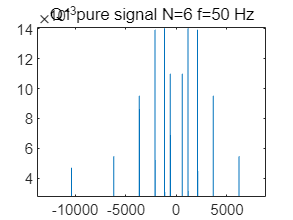

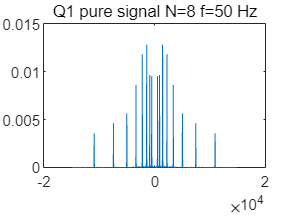

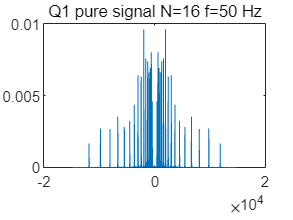

clc;clear;clf;

[x, fs] = audioread ("C_01_02.wav");

ctof_fq = 50;
but_order = 1;

for i = [4 6 8 16]
    y = tone_vocoder(x,i,ctof_fq,but_order,fs);
    Y = fft(y)/length(y);
    figure
    plot(1-14819:29636-14819,abs(fftshift(Y)));
    title(sprintf('Q1 pure signal N=%d f=50 Hz',i))
    audiowrite(sprintf('Q1 pure signal N=%d f=50 Hz.wav',i),y,fs)
end

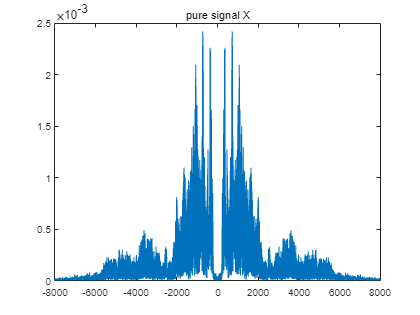

N = 8;
figure
X = fft(x)/length(x);
figure
f = linspace(-fs/2, fs/2, length(x));
plot(f,abs(fftshift(X)));
title('pure signal X')

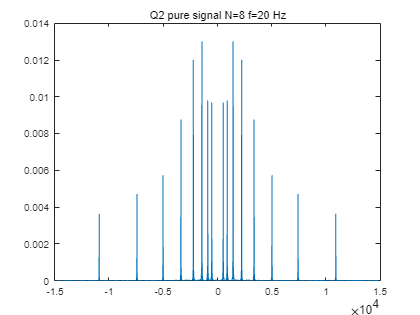

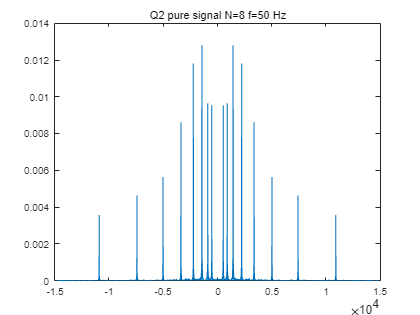

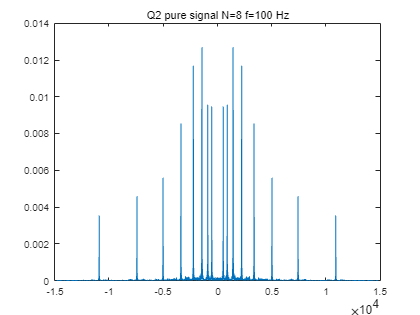

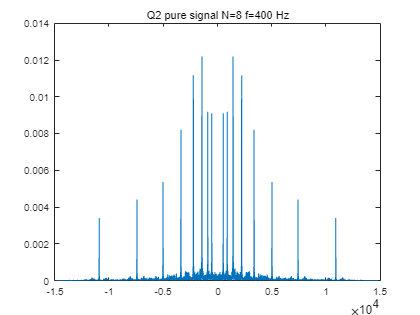

for i = [20 50 100 400]
    y = tone_vocoder(x,N,i,but_order,fs);
    figure
    Y = fft(y)/length(y);
    figure
    plot(1-14819:29636-14819,abs(fftshift(Y)));
    title(sprintf('Q2 pure signal N=8 f=%d Hz',i))
    audiowrite(sprintf('Q2 pure signal N=8 f=%d Hz.wav',i),y,fs)
end

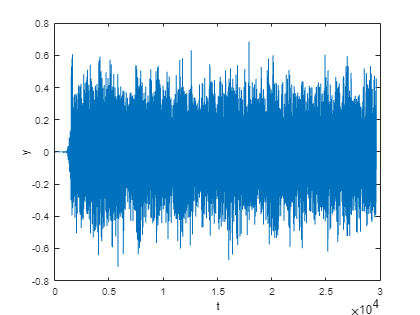

N = length(x);
noise = (1-2*rand(N,1));
sig = repmat(x,10,1);
[Pxx,w] = pwelch(sig,[],[],512,fs);
b=fir2(3000,w/(fs/2),sqrt(Pxx/max(Pxx)));
[h, wh] = freqz(b,1,128);
noise = filter(b,1,noise);
Enoise = norm(noise);
Ex = norm(x);

Eknosie = 10^(1/2)*Ex;
k = Eknosie/Enoise;
y = x + k*noise;
Ey = norm(y);
m = Ey/Ex;
y_Final = y./m;
figure
plot(y_Final);
xlabel('t')
ylabel('y')

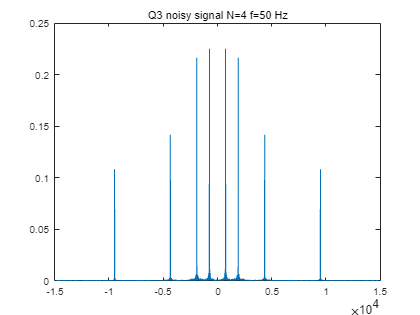

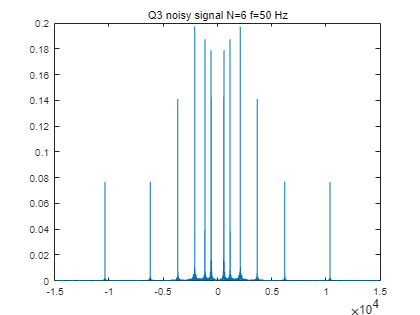

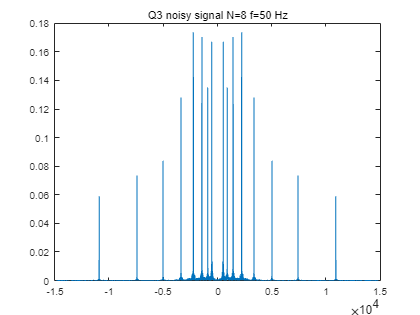

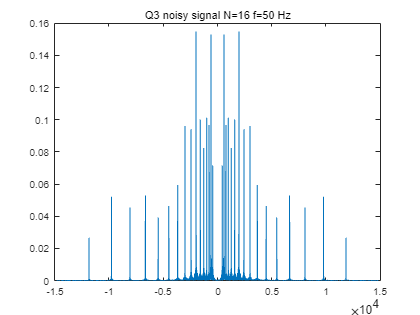

% 获得有言语谱噪声的信号
audiowrite(sprintf('noisy_and_sentence_m5dB.wav',i),x,fs);
x = y;
ctof_fq = 50;
but_order = 1;

for i = [4 6 8 16]
    y = tone_vocoder(x,i,ctof_fq,but_order,fs);
    Y = fft(y)/length(y);
    figure
    plot(1-14819:29636-14819,abs(fftshift(Y)));
    title(sprintf('Q3 noisy signal N=%d f=50 Hz',i))
    audiowrite(sprintf('Q3 noisy signal N=%d f=50 Hz.wav',i),y,fs)
end

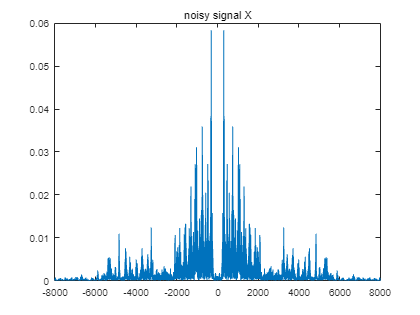

N = 6;
figure
X = fft(x)/length(x);
f = linspace(-fs/2, fs/2, length(x));
figure
plot(f,abs(fftshift(X)));
title('noisy signal X')

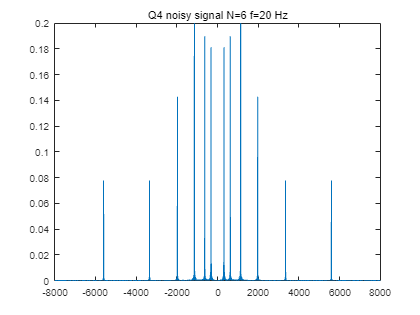

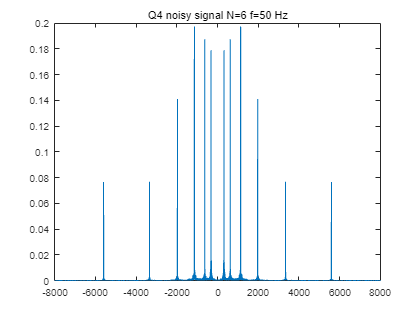

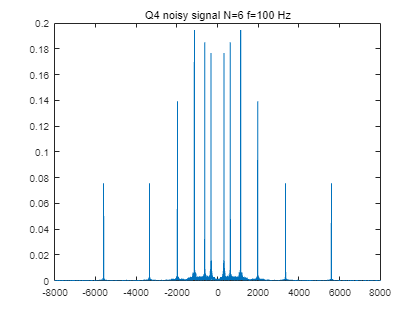

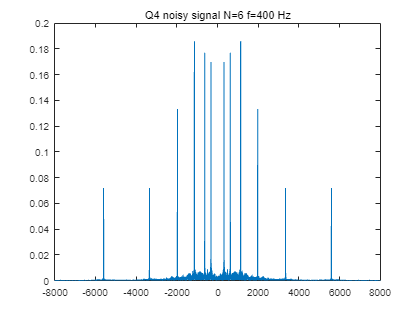

for i = [20 50 100 400]
    y = tone_vocoder(x,N,i,but_order,fs);
    figure
    Y = fft(y)/length(y);
    figure
    plot(f,abs(fftshift(Y)));
    title(sprintf('Q4 noisy signal N=%d f=%d Hz',N, i))
    audiowrite(sprintf('Q4 noisy signal N=%d f=%d Hz.wav',N, i),y,fs)
end